# **Validation -- Merbouche Mouloud & Tso Célia**

clear; close all; clc
digits(4);

load('sol.mat','sol');
load('id_struct.mat','idx_ind','p');   
load('validation.mat'); 

q4 = q_meas_validation(1:4, :);

I4 = tau_meas_validation(1:4, :);     

Kc = [0.38; 0.38; 0.22; 0.21];         
Gr = [120; 160; 120; 100];            



Tau4 = (Kc .* Gr) .* I4;           

q_conv = q4;
q_conv([1 2 4], :) = deg2rad(q4([1 2 4], :));
q_conv(3, :)       = q4(3, :) / 1000;

fc = 10;
fe = 1000;
Wn = 2 * fc / fe;
[b, a] = butter(1, Wn);

[n_joints, n_samples] = size(q_conv);

qf   = zeros(n_joints, n_samples);
dqf  = zeros(n_joints, n_samples);
ddqf = zeros(n_joints, n_samples);
tauf = zeros(n_joints, n_samples);

for i = 1:n_joints
    qf(i, :)   = filtfilt(b, a, q_conv(i, :));
    tauf(i, :) = filtfilt(b, a, Tau4(i, :));

    dq_raw     = derive(t, qf(i, :));
    dqf(i, :)  = filtfilt(b, a, dq_raw);

    ddq_raw    = derive(t, dqf(i, :));
    ddqf(i, :) = filtfilt(b, a, ddq_raw);
end


type = [1;1;0;1];
n = 4;
d = [ 0 ; 0.22 ; 0.24 ; 0 ];
alph = [ 0 ; 0 ; 0 ; 0 ] ;
r = [ 0 ; 0 ; 0 ; 0 ] ;
th = [ 0 ; 0 ; 0 ; 0 ] ;
V_g = [ 0 ; 0 ; 9.81 ] ;

m = sym("m",[ n 1 ],'real') ;
xx= sym("xx",[ n 1 ],'real') ;
yy= sym("yy",[ n 1 ],'real') ;
zz= sym("zz",[ n 1 ],'real') ;
xy= sym("xy",[ n 1 ],'real') ;
xz= sym("xz",[ n 1 ],'real') ;
yz= sym("yz",[ n 1 ],'real') ;

for k = 1 : n
Ig(:,:,k) = [ xx(k) xy(k) xz(k) ; xy(k) yy(k) yz(k) ;
xz(k) yz(k) zz(k) ];
end
x= sym("x",[ n 1 ],'real') ;
y= sym("y",[ n 1 ],'real') ;
z= sym("z",[ n 1 ],'real') ;
for k = 1:n
    rcm(:, k) = [x(k); y(k); z(k)];
end

for k = 1:n
    rcm_skew(:,:,k) = skew(rcm(:, k));
end


Fc = sym('Fc', [n 1], 'real');
Fv = sym('Fv', [n 1], 'real'); 
%p.15
nn = (length(t)-1)/380;
for k = 1 : nn
t_sub(1,k) = t(1,(k-1)*380+1);
q_sub(:,k) = qf(:,(k-1)*380+1);
dq_sub(:,k) = dqf(:,(k-1)*380+1);
ddq_sub(:,k) = ddqf(:,(k-1)*380+1);
tau_sub(:,k) = tauf(:,(k-1)*380+1);
end

tau_id = sym(zeros(n,nn));

for mm = 1:nn
%for mm = 1:10 si pas réussi a faire l'optimisation
mm
th(1) = q_sub(1,mm);
th(2) = q_sub(2,mm);
r(3) = q_sub(3,mm);
th(4) = q_sub(4,mm);
qp = dq_sub(:,mm);
qpp = ddq_sub(:,mm);

%p.18
for k = 1:n
        T(:,:,k) = [ cos(th(k))               , - sin(th(k))              , 0             , d(k) ;
                    cos(alph(k)) * sin(th(k)) , cos(alph(k)) * cos(th(k)) , -sin(alph(k)) , - r(k) * sin(alph(k)) ;
                    sin(alph(k)) * sin(th(k)) , sin(alph(k)) * cos(th(k)) , cos(alph(k))  , r(k) * cos(alph(k)) ;
                    0                         , 0                         , 0             , 1 ];
end

Ti(:,:,1) = T(:,:,1);
for k = 2 : n
Ti(:,:,k) = Ti(:,:,k-1) * T(:,:,k);
end

zi(:,1:n) = Ti(1:3,3,1:n);
ti(:,1:n) = Ti(1:3,4,1:n);
Ri(:,:,1:n) = Ti(1:3,1:3,1:n);

%p.20-21
for i = 1 : n
for k = 1 : i
li(:,k,i) = ti(:,i) - ti(:,k);
Jvi(:,k,i) = cross(zi(:,k) , li(:,k,i));
Jwi(:,k,i) = zi(:,k);
end
end

for i = 1 : n
Jgi(:,:,i) = Jvi(:,:,i) - Ri(:,:,i) * rcm_skew(:,:,i) * (Ri(:,:,i))' * Jwi(:,:,i);
end

M = m(1) * (Jgi(:,:,1))' * Jgi(:,:,1) + (Jwi(:,:,1))' * Ri(:,:,1) * Ig(:,:,1) * (Ri(:,:,1))' * Jwi(:,:,1);
for k = 2 : n
M = M + m(k) * (Jgi(:,:,k))' * Jgi(:,:,k) + (Jwi(:,:,k))' * Ri(:,:,k) * Ig(:,:,k) * (Ri(:,:,k))' *Jwi(:,:,k);
end

%M = m(1) * (Jgi(:,:,1))' * Jgi(:,:,1) + (Jwi(:,:,1))' * Ri(:,:,1) * Ig(:,:,1) * (Ri(:,:,1))' * Jwi(:,:,1);
%for k = 2 : n
%M = M + m(k) * (Jgi(:,:,k))' * Jgi(:,:,k) + (Jwi(:,:,k))' * Ri(:,:,k) * Ig(:,:,k) * (Ri(:,:,k))' * Jwi(:,:,k);
%end


%p.23-24
for k = 1 : n
if type(k) == 1
dT(:,:,k) = [ - sin(th(k)) , - cos(th(k)) , 0 , 0 ;
cos(alph(k)) * cos(th(k)) , - cos(alph(k)) * sin(th(k)) , 0 , 0 ;
sin(alph(k)) * cos(th(k)) , - sin(alph(k)) * sin(th(k)), 0 , 0 ;
0 , 0 , 0 , 1 ];
elseif type(k) == 0
dT(:,:,k) = [ 0 , 0 , 0 , 0 ;
0 , 0 , 0 , - sin(alph(k)) ;
0 , 0 , 0 , cos(alph(k)) ;
0 , 0 , 0 , 1 ];
end
end


%P.25
for i = 1 : n
for j = 1 : n
if j > i
dTij(:,:,i,j) = zeros(4);
elseif j == i
if j == 1
dTij(:,:,i,j) = dT(:,:,j);
else
dTij(:,:,i,j) = Ti(:,:,j-1) * dT(:,:,j);
end
else
if j == 1
Tij = eye(4);
for k = j + 1 : i
Tij = Tij * Ti(:,:,k);
end

dTij(:,:,i,j) = dT(:,:,j) * Tij;
else
Tij = eye(4);
for k = j + 1 : i
Tij = Tij * Ti(:,:,k);
end
dTij(:,:,i,j) = Ti(:,:,j-1) * dT(:,:,j) * Tij;
end
end
dRij(:,:,i,j) = dTij(1:3,1:3,i,j);
dzij(:,i,j) = dTij(1:3,3,i,j);
dtij(:,i,j) = dTij(1:3,4,i,j);
end
end

for j = 1 : n
G(j,1) = m(1) * V_g' * (dtij(:,1,j) + dRij(:,:,1,j) * rcm(:,1));
for i = 2 : n
G(j,1) = G(j,1) + m(i) * V_g' * (dtij(:,i,j) + dRij(:,:,i,j) * rcm(:,i));
end
end

%for j = 1 : n
%G(j,1) = m(1) * V_g' * (dtij(:,1,j) + dRij(:,:,1,j) * rcm(:,1));
%for i = 2 : n
%G(j,1) = G(j,1) + m(i) * V_g' * (dtij(:,i,j) + dRij(:,:,i,j) * rcm(:,i));
%end
%end

for i = 1 : n
for k = 1 : i
for j = 1 : n
dlij(:,k,i,j) = dtij(:,i,j) - dtij(:,k,j);
dJvi(:,k,i,j) = cross(dzij(:,k,j),li(:,k,i)) + cross(zi(:,k),dlij(:,k,i,j));
dJwi(:,k,i,j)  = dzij(:,k,j); 
end
end
end


for i = 1 : n
for j = 1 : n
dJgi(:,:,i,j) = dJvi(:,:,i,j) - dRij(:,:,i,j) * rcm_skew(:,:,i) * (Ri(:,:,i))' * Jwi(:,:,i) - Ri(:,:,i) * rcm_skew(:,:,i) * (dRij(:,:,i,j))' * Jwi(:,:,i) - Ri(:,:,i) * rcm_skew(:,:,i) * (Ri(:,:,i))' * dJwi(:,:,i,j);
%dJgi(:,:,i,j) = dJvi(:,:,i,j) - dRij(:,:,i,j) * rcm_skew(:,:,i) * (Ri(:,:,i))' * Jwi(:,:,i) - Ri(:,:,i) * rcm_skew(:,:,i) * (dRij(:,:,i,j))' * Jwi(:,:,i) - Ri(:,:,i) * rcm_skew(:,:,i) * (Ri(:,:,i))' * dJwi(:,:,i,j);
end
end


for j = 1 : n
    % Initialisation avec le premier corps (i=1) - Page 31
    dMj(:,:,j) = m(1) * ( (dJgi(:,:,1,j))' * Jgi(:,:,1) + (Jgi(:,:,1))' * dJgi(:,:,1,j) ) + ...
                 (dJwi(:,:,1,j))' * Ri(:,:,1) * Ig(:,:,1) * (Ri(:,:,1))' * Jwi(:,:,1) + ...
                 (Jwi(:,:,1))' * dRij(:,:,1,j) * Ig(:,:,1) * (Ri(:,:,1))'* Jwi(:,:,1) + ...
                 (Jwi(:,:,1))' * Ri(:,:,1) * Ig(:,:,1) * (dRij(:,:,1,j))' * Jwi(:,:,1) + ...
                 (Jwi(:,:,1))' * Ri(:,:,1) * Ig(:,:,1) * (Ri(:,:,1))' * dJwi(:,:,1,j);
    
    % Sommation pour les corps suivants (i=2 à n) - Page 32
    for i = 2 : n
        dMj(:,:,j) = (dMj(:,:,j) + m(i) * ( (dJgi(:,:,i,j))' * Jgi(:,:,i) + (Jgi(:,:,i))' * dJgi(:,:,i,j) ) + ...
                     (dJwi(:,:,i,j))' * Ri(:,:,i) * Ig(:,:,i) * (Ri(:,:,i))' * Jwi(:,:,i) + ...
                     (Jwi(:,:,i))' * dRij(:,:,i,j) * Ig(:,:,i) * (Ri(:,:,i))' * Jwi(:,:,i) + ...
                     (Jwi(:,:,i))' * Ri(:,:,i) * Ig(:,:,i) * (dRij(:,:,i,j))' * Jwi(:,:,i) + ...
                     (Jwi(:,:,i))' * Ri(:,:,i) * Ig(:,:,i) * (Ri(:,:,i))' * dJwi(:,:,i,j));
    end
end 

Mp = ((dMj(:,:,1) * qp(1)));
%Mp = dMj(:,:,1) * qp(1);
for j = 2 : n
    Mp = (Mp + dMj(:,:,j) * qp(j));
    %Mp = Mp + dMj(:,:,j) * qp(j);
end


for j = 1 : n
N2(j,:) = (qp' * dMj(:,:,j));
%N2(j,:) = qp' * dMj(:,:,j);
end
N = (Mp - 1/2 * N2);
%N = Mp - 1/2 * N2;


%tau_id(:,mm) = simplify((M * qpp + N * qp + G - Fv .* qp - Fc .* sign(qp)));
tau_id(:,mm) = simplify(vpa(M * qpp + N * qp + G - Fv .* qp - Fc .* sign(qp)));
end

mm = 1

mm = 2

mm = 3

mm = 4

mm = 5

mm = 6

mm = 7

mm = 8

mm = 9

mm = 10

mm = 11

mm = 12

mm = 13

mm = 14

mm = 15

mm = 16

mm = 17

mm = 18

mm = 19

mm = 20

mm = 21

mm = 22

mm = 23

mm = 24

mm = 25

mm = 26

mm = 27

mm = 28

mm = 29

mm = 30

mm = 31

mm = 32

mm = 33

mm = 34

mm = 35

mm = 36

mm = 37

mm = 38

mm = 39

mm = 40

mm = 41

mm = 42

mm = 43

mm = 44

mm = 45

mm = 46

mm = 47

mm = 48

mm = 49

mm = 50

mm = 51

mm = 52

mm = 53

mm = 54

mm = 55

mm = 56

mm = 57

mm = 58

mm = 59

mm = 60

mm = 61

mm = 62

mm = 63

mm = 64

mm = 65

mm = 66

mm = 67

mm = 68

mm = 69

mm = 70

mm = 71

mm = 72

mm = 73

mm = 74

mm = 75

mm = 76

mm = 77

mm = 78

mm = 79

mm = 80

mm = 81

mm = 82

mm = 83

mm = 84

mm = 85

mm = 86

mm = 87

mm = 88

mm = 89

mm = 90

mm = 91

mm = 92

mm = 93

mm = 94

mm = 95

mm = 96

mm = 97

mm = 98

mm = 99

mm = 100

mm = 101

mm = 102

mm = 103

mm = 104

mm = 105

mm = 106

mm = 107

mm = 108

mm = 109

mm = 110

mm = 111

mm = 112

mm = 113

mm = 114

mm = 115

mm = 116

mm = 117

mm = 118

mm = 119

mm = 120

mm = 121

mm = 122

mm = 123

mm = 124

mm = 125

mm = 126

mm = 127

mm = 128

mm = 129

mm = 130

mm = 131

mm = 132

mm = 133

mm = 134

mm = 135

mm = 136

mm = 137

mm = 138

mm = 139

mm = 140

mm = 141

mm = 142

mm = 143

mm = 144

mm = 145

mm = 146

mm = 147

mm = 148

mm = 149

mm = 150

mm = 151

mm = 152

mm = 153

mm = 154

mm = 155

mm = 156

mm = 157

mm = 158

mm = 159

mm = 160

mm = 161

mm = 162

mm = 163

mm = 164

mm = 165

mm = 166

mm = 167

mm = 168

mm = 169

mm = 170

mm = 171

mm = 172

mm = 173

mm = 174

mm = 175

mm = 176

mm = 177

mm = 178

mm = 179

mm = 180

mm = 181

mm = 182

mm = 183

mm = 184

mm = 185

mm = 186

mm = 187

mm = 188

mm = 189

mm = 190

mm = 191

mm = 192

mm = 193

mm = 194

mm = 195

mm = 196

mm = 197

mm = 198

mm = 199

mm = 200

mm = 201

mm = 202

mm = 203

mm = 204

mm = 205

mm = 206

mm = 207

mm = 208

mm = 209

mm = 210

mm = 211

mm = 212

mm = 213

mm = 214

mm = 215

mm = 216

mm = 217

mm = 218

mm = 219

mm = 220

mm = 221

mm = 222

mm = 223

mm = 224

mm = 225

mm = 226

mm = 227

mm = 228

mm = 229

mm = 230

mm = 231

mm = 232

mm = 233

mm = 234

mm = 235

mm = 236

mm = 237

mm = 238

mm = 239

mm = 240

mm = 241

mm = 242

mm = 243

mm = 244

mm = 245

mm = 246

mm = 247

mm = 248

mm = 249

mm = 250

mm = 251

mm = 252

mm = 253

mm = 254

mm = 255

mm = 256

mm = 257

mm = 258

mm = 259

mm = 260

mm = 261

mm = 262

mm = 263

mm = 264

mm = 265

mm = 266

mm = 267

mm = 268

mm = 269

mm = 270

mm = 271

mm = 272

mm = 273

mm = 274

mm = 275

mm = 276

mm = 277

mm = 278

mm = 279

mm = 280

mm = 281

mm = 282

mm = 283

mm = 284

mm = 285

mm = 286

mm = 287

mm = 288

mm = 289

mm = 290

mm = 291

mm = 292

mm = 293

mm = 294

mm = 295

mm = 296

mm = 297

mm = 298

mm = 299

mm = 300

mm = 301

mm = 302

mm = 303

mm = 304

mm = 305

mm = 306

mm = 307

mm = 308

mm = 309

mm = 310

mm = 311

mm = 312

mm = 313

mm = 314

mm = 315

mm = 316

mm = 317

mm = 318

mm = 319

mm = 320

mm = 321

mm = 322

mm = 323

mm = 324

mm = 325

mm = 326

mm = 327

mm = 328

mm = 329

mm = 330

mm = 331

mm = 332

mm = 333

mm = 334

mm = 335

mm = 336

mm = 337

mm = 338

mm = 339

mm = 340

mm = 341

mm = 342

mm = 343

mm = 344

mm = 345

mm = 346

mm = 347

mm = 348

mm = 349

mm = 350

mm = 351

mm = 352

mm = 353

mm = 354

mm = 355

mm = 356

mm = 357

mm = 358

mm = 359

mm = 360

mm = 361

mm = 362

mm = 363

mm = 364

mm = 365

mm = 366

mm = 367

mm = 368

mm = 369

mm = 370

mm = 371

mm = 372

mm = 373

mm = 374

mm = 375

mm = 376

mm = 377

mm = 378

mm = 379

mm = 380

mm = 381

mm = 382

mm = 383

mm = 384

mm = 385

mm = 386

mm = 387

mm = 388

mm = 389

mm = 390

mm = 391

mm = 392

mm = 393

mm = 394

mm = 395

mm = 396

mm = 397

mm = 398

mm = 399

mm = 400

mm = 401

mm = 402

mm = 403

mm = 404

mm = 405

mm = 406

mm = 407

mm = 408

mm = 409

mm = 410

mm = 411

mm = 412

mm = 413

mm = 414

mm = 415

mm = 416

mm = 417

mm = 418

mm = 419

mm = 420

mm = 421

mm = 422

mm = 423

mm = 424

mm = 425

mm = 426

mm = 427

mm = 428

mm = 429

mm = 430

mm = 431

mm = 432

mm = 433

mm = 434

mm = 435

mm = 436

mm = 437

mm = 438

mm = 439

mm = 440

mm = 441

mm = 442

mm = 443

mm = 444

mm = 445

mm = 446

mm = 447

mm = 448

mm = 449

mm = 450

mm = 451

mm = 452

mm = 453

mm = 454

mm = 455

mm = 456

mm = 457

mm = 458

mm = 459

mm = 460

mm = 461

mm = 462

mm = 463

mm = 464

mm = 465

mm = 466

mm = 467

mm = 468

mm = 469

mm = 470

mm = 471

mm = 472

mm = 473

mm = 474

mm = 475

mm = 476

mm = 477

mm = 478

mm = 479

mm = 480

mm = 481

mm = 482

mm = 483

mm = 484

mm = 485

mm = 486

mm = 487

mm = 488

mm = 489

mm = 490

mm = 491

mm = 492

mm = 493

mm = 494

mm = 495

mm = 496

mm = 497

mm = 498

mm = 499

mm = 500

mm = 501

mm = 502

mm = 503

mm = 504

mm = 505

mm = 506

mm = 507

mm = 508

mm = 509

mm = 510

mm = 511

mm = 512

mm = 513

mm = 514

mm = 515

mm = 516

mm = 517

mm = 518

mm = 519

mm = 520

mm = 521

mm = 522

mm = 523

mm = 524

mm = 525

mm = 526

mm = 527

mm = 528

mm = 529

mm = 530

mm = 531

mm = 532

mm = 533

mm = 534

mm = 535

mm = 536

mm = 537

mm = 538

mm = 539

mm = 540

mm = 541

mm = 542

mm = 543

mm = 544

mm = 545

mm = 546

mm = 547

mm = 548

mm = 549

mm = 550

mm = 551

mm = 552

mm = 553

mm = 554

mm = 555

mm = 556

mm = 557

mm = 558

mm = 559

mm = 560

mm = 561

mm = 562

mm = 563

mm = 564

mm = 565

mm = 566

mm = 567

mm = 568

mm = 569

mm = 570

mm = 571

mm = 572

mm = 573

mm = 574

mm = 575

mm = 576

mm = 577

mm = 578

mm = 579

mm = 580

mm = 581

mm = 582

mm = 583

mm = 584

mm = 585

mm = 586

mm = 587

mm = 588

mm = 589

mm = 590

mm = 591

mm = 592

mm = 593

mm = 594

mm = 595

mm = 596

mm = 597

mm = 598

mm = 599

mm = 600

mm = 601

mm = 602

mm = 603

mm = 604

mm = 605

mm = 606

mm = 607

mm = 608

mm = 609

mm = 610

mm = 611

mm = 612

mm = 613

mm = 614

mm = 615

mm = 616

mm = 617

mm = 618

mm = 619

mm = 620

mm = 621

mm = 622

mm = 623

mm = 624

mm = 625

mm = 626

mm = 627

mm = 628

mm = 629

mm = 630

mm = 631

mm = 632

mm = 633

mm = 634

mm = 635

mm = 636

mm = 637

mm = 638

mm = 639

mm = 640

mm = 641

mm = 642

mm = 643

mm = 644

mm = 645

mm = 646

mm = 647

mm = 648

mm = 649

mm = 650

mm = 651

mm = 652

mm = 653

mm = 654

mm = 655

mm = 656

mm = 657

mm = 658

mm = 659

mm = 660

mm = 661

mm = 662

mm = 663

mm = 664

mm = 665

mm = 666

mm = 667

mm = 668

mm = 669

mm = 670

mm = 671

mm = 672

mm = 673

mm = 674

mm = 675

mm = 676

mm = 677

mm = 678

mm = 679

mm = 680

mm = 681

mm = 682

mm = 683

mm = 684

mm = 685

mm = 686

mm = 687

mm = 688

mm = 689

mm = 690

mm = 691

mm = 692

mm = 693

mm = 694

mm = 695

mm = 696

mm = 697

mm = 698

mm = 699

mm = 700

mm = 701

mm = 702

mm = 703

mm = 704

mm = 705

mm = 706

mm = 707

mm = 708

mm = 709

mm = 710

mm = 711

mm = 712

mm = 713

mm = 714

mm = 715

mm = 716

mm = 717

mm = 718

mm = 719

mm = 720

mm = 721

mm = 722

mm = 723

mm = 724

mm = 725

mm = 726

mm = 727

mm = 728

mm = 729

mm = 730

mm = 731

mm = 732

mm = 733

mm = 734

mm = 735

mm = 736

mm = 737

mm = 738

mm = 739

mm = 740

mm = 741

mm = 742

mm = 743

mm = 744

mm = 745

mm = 746

mm = 747

mm = 748

mm = 749

mm = 750

mm = 751

mm = 752

mm = 753

mm = 754

mm = 755

mm = 756

mm = 757

mm = 758

mm = 759

mm = 760

mm = 761

mm = 762

mm = 763

mm = 764

mm = 765

mm = 766

mm = 767

mm = 768

mm = 769

mm = 770

mm = 771

mm = 772

mm = 773

mm = 774

mm = 775

mm = 776

mm = 777

mm = 778

mm = 779

mm = 780

mm = 781

mm = 782

mm = 783

mm = 784

mm = 785

mm = 786

mm = 787

mm = 788

mm = 789

mm = 790

mm = 791

mm = 792

mm = 793

mm = 794

mm = 795

mm = 796

mm = 797

mm = 798

mm = 799

mm = 800

mm = 801

mm = 802

mm = 803

mm = 804

mm = 805

mm = 806

mm = 807

mm = 808

mm = 809

mm = 810

mm = 811

mm = 812

mm = 813

mm = 814

mm = 815

mm = 816

mm = 817

mm = 818

mm = 819

mm = 820

mm = 821

mm = 822

mm = 823

mm = 824

mm = 825

mm = 826

mm = 827

mm = 828

mm = 829

mm = 830

mm = 831

mm = 832

mm = 833

mm = 834

mm = 835

mm = 836

mm = 837

mm = 838

mm = 839

mm = 840

mm = 841

mm = 842

mm = 843

mm = 844

mm = 845

mm = 846

mm = 847

mm = 848

mm = 849

mm = 850

mm = 851

mm = 852

mm = 853

mm = 854

mm = 855

mm = 856

mm = 857

mm = 858

mm = 859

mm = 860

mm = 861

mm = 862

mm = 863

mm = 864

mm = 865

mm = 866

mm = 867

mm = 868

mm = 869

mm = 870

mm = 871

mm = 872

mm = 873

mm = 874

mm = 875

mm = 876

mm = 877

mm = 878

mm = 879

mm = 880

mm = 881

mm = 882

mm = 883

mm = 884

mm = 885

mm = 886

mm = 887

mm = 888

mm = 889

mm = 890

mm = 891

mm = 892

mm = 893

mm = 894

mm = 895

mm = 896

mm = 897

mm = 898

mm = 899

mm = 900

mm = 901

mm = 902

mm = 903

mm = 904

mm = 905

mm = 906

mm = 907

mm = 908

mm = 909

mm = 910

mm = 911

mm = 912

mm = 913

mm = 914

mm = 915

mm = 916

mm = 917

mm = 918

mm = 919

mm = 920

mm = 921

mm = 922

mm = 923

mm = 924

mm = 925

mm = 926

mm = 927

mm = 928

mm = 929

mm = 930

mm = 931

mm = 932

mm = 933

mm = 934

mm = 935

mm = 936

mm = 937

mm = 938

mm = 939

mm = 940

mm = 941

mm = 942

mm = 943

mm = 944

mm = 945

mm = 946

mm = 947

mm = 948

mm = 949

mm = 950

mm = 951

mm = 952

mm = 953

mm = 954

mm = 955

mm = 956

mm = 957

mm = 958

mm = 959

mm = 960

mm = 961

mm = 962

mm = 963

mm = 964

mm = 965

mm = 966

mm = 967

mm = 968

mm = 969

mm = 970

mm = 971

mm = 972

mm = 973

mm = 974

mm = 975

mm = 976

mm = 977

mm = 978

mm = 979

mm = 980

mm = 981

mm = 982

mm = 983

mm = 984

mm = 985

mm = 986

mm = 987

mm = 988

mm = 989

mm = 990

mm = 991

mm = 992

mm = 993

mm = 994

mm = 995

mm = 996

mm = 997

mm = 998

mm = 999

mm = 1000

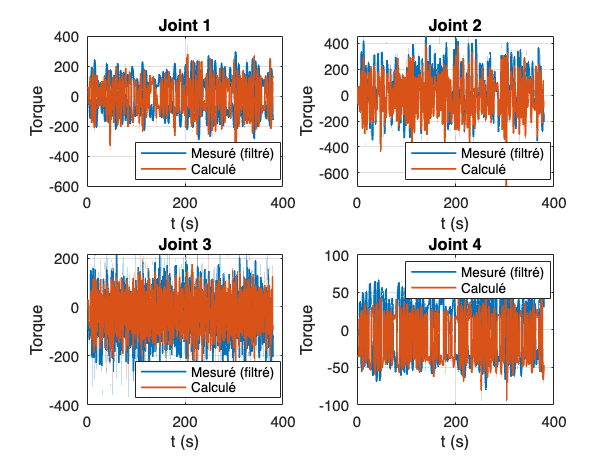

%%
[row, col] = size(tau_sub);

tau_id_conca  = sym(zeros(row*col,1));
tau_sub_conca = zeros(row*col,1);
for k = 1:col
    tau_sub_conca(row*(k-1)+1:row*k,1) = tau_sub(:,k);
    tau_id_conca(row*(k-1)+1:row*k,1)  = tau_id(:,k);
end

mx    = sym("mx",[n 1],'real'); my = sym("my",[n 1],'real'); mz = sym("mz",[n 1],'real');
mxy   = sym("mxy",[n 1],'real'); myz = sym("myz",[n 1],'real'); mxz = sym("mxz",[n 1],'real');
mx_sq = sym("mx_sq",[n 1],'real'); my_sq = sym("my_sq",[n 1],'real'); mz_sq = sym("mz_sq",[n 1],'real');

old = [ m.*x.*y ; m.*y.*z ; m.*x.*z ; m.*x.*x ; m.*y.*y ; m.*z.*z ; m.*x ; m.*y ; m.*z ];
new = [ mxy ; myz ; mxz ; mx_sq ; my_sq ; mz_sq ; mx ; my ; mz ];

tau_id_conca_new = subs(tau_id_conca, old, new);
eqns = tau_id_conca_new == tau_sub_conca;

[D_val, ~] = equationsToMatrix(eqns, p);
D_real_val = round(double(D_val), 5);

Db_val = D_real_val(:, idx_ind);

assert(size(Db_val,2) == length(sol), "Db_val et sol ne sont pas compatibles (idx_ind / sol mismatch).");

tau_c_conca = Db_val * sol;
tau_c = reshape(tau_c_conca, n, nn);

figure('Name','Validation: mesuré vs (Db_val*sol)');
for j = 1:n
    subplot(2,2,j);
    plot(t_sub, tau_sub(j,:), 'LineWidth', 1.2); hold on
    plot(t_sub, tau_c(j,:),   'LineWidth', 1.2);
    grid on
    xlabel('t (s)');
    ylabel('Torque');
    title(['Joint ', num2str(j)]);
    legend('Mesuré (filtré)', 'Calculé', 'Location','best');
end


%%%% functions %%%%%
function df = derive(t, f)
    df = [ f(1,2) - f(1,1), ...
           (f(1,3:end) - f(1,1:end-2)) / 2, ...
           f(1,end) - f(1,end-1) ] / (t(1,2) - t(1,1));
end

function S = skew(v)
    S = [  0   -v(3)  v(2);
          v(3)   0   -v(1);
         -v(2)  v(1)   0 ];
end
